# Location Analysis

clear;
clc;

## Wild Type

### n=1

WT_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=1/results_from_time_0/location.dat";
[WT_1_LuminalPositions, WT_1_MyoepithelialPositions, WT_1_r, WT_1_r2] = CellPosition(WT_1);

### n=2

WT_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=2/results_from_time_0/location.dat";
[WT_2_LuminalPositions, WT_2_MyoepithelialPositions, WT_2_r, WT_2_r2] = CellPosition(WT_2);

### n=3

WT_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=3/results_from_time_0/location.dat";
[WT_3_LuminalPositions, WT_3_MyoepithelialPositions, WT_3_r, WT_3_r2] = CellPosition(WT_3);

### n=4

WT_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=4/results_from_time_0/location.dat";
[WT_4_LuminalPositions, WT_4_MyoepithelialPositions, WT_4_r, WT_4_r2] = CellPosition(WT_4);

### n=5

WT_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=5/results_from_time_0/location.dat";
[WT_5_LuminalPositions, WT_5_MyoepithelialPositions, WT_5_r, WT_5_r2] = CellPosition(WT_5);

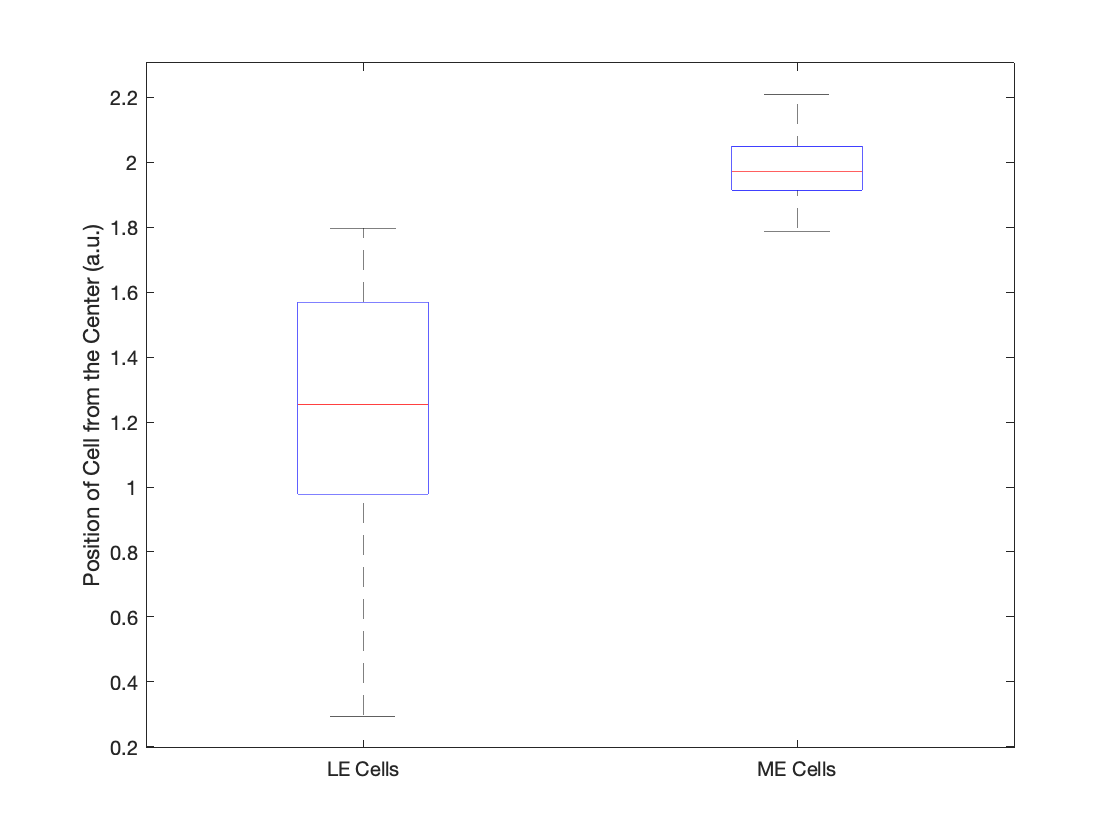

% Box plot final position of cells

figure 

WTluminal = WT_1_r(end,:);
WTmyo = WT_1_r2(end,:);
g = [WTluminal WTmyo];
C = [zeros(1,length(WTluminal)) ones(1,length(mWTyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_WT.pdf');

movefile('CellPosition_WT.pdf', folder);

% combine data from all experiments
WTLEposition = cat(1,WT_1_r(end,:),WT_2_r(end,:),WT_3_r(end,:),WT_4_r(end,:),WT_5_r(end,:));
WTMEposition = cat(1,WT_1_r2(end,:),WT_2_r2(end,:),WT_3_r2(end,:),WT_4_r2(end,:),WT_5_r2(end,:));

%Calculate Mean
WTLEaverage = mean(WTLEposition,2);
WTMEaverage = mean(WTMEposition,2);

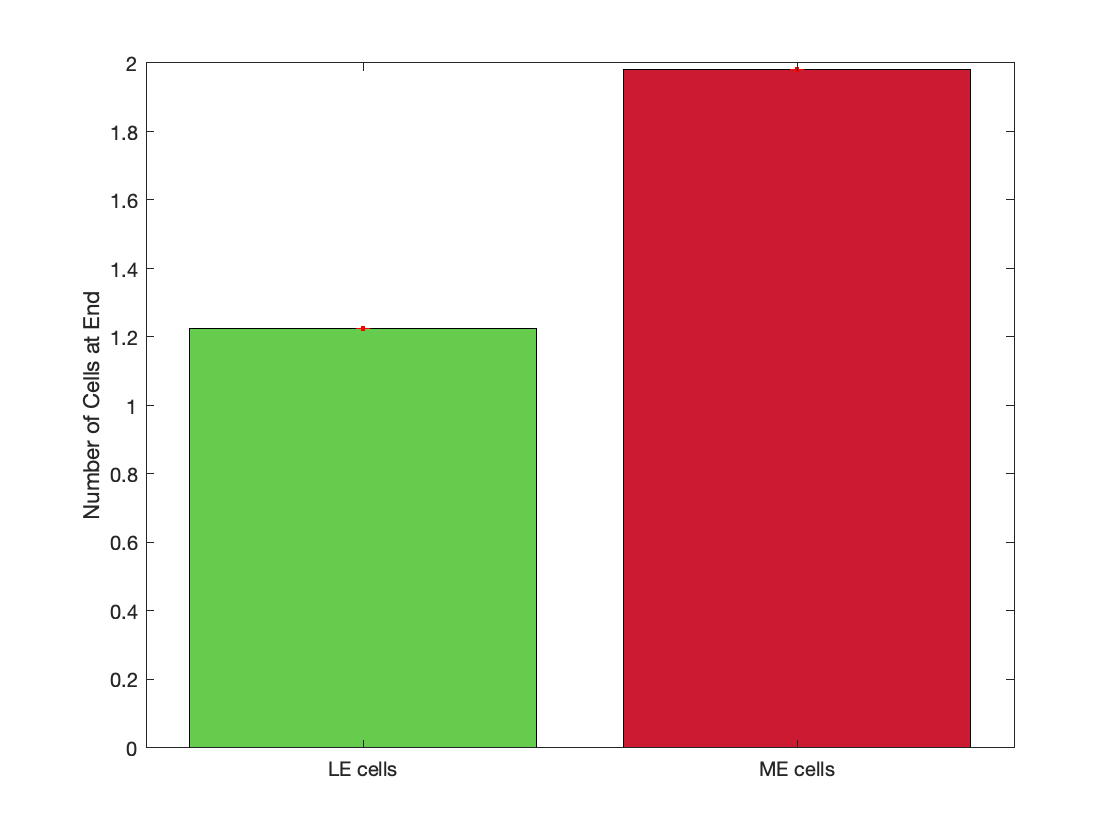

% plot average position of cells include data from all n=5 

%Calculate Mean and Standard Deviation
WTmeanLE = mean(WTLEaverage);
WTmeanME = mean(WTMEaverage);

y = cat(2, WTmeanLE, WTmeanME);

WTstdLE = std(WTLEaverage);
WTstdME = std(WTMEaverage);

error = cat(2, WTstdLE, WTstdME);

x=categorical({'LE cells', 'ME cells'});

b = bar(x,y);

%Make SD error bars 
hold on
errorbar(x,y, error, '.r')
hold off

ylabel('Number of Cells at End') 
ax.XTickLabels = {'LE Cells', 'ME Cells'};

b.FaceColor = 'flat';
b.CData(1,:) = [.4 .8 .3];
b.CData(2,:) = [.8 .1 .2];

hold off

folder = '~/Desktop/';
exportgraphics(gca, 'AverageCellPosition_WT.pdf');

movefile('AverageCellPosition_WT.pdf', folder);

## ME B1 KO

### n=1

MEB1KO_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=1/results_from_time_0/location.dat";
[MEB1KO_1_LuminalPositions, MEB1KO_1_MyoepithelialPositions, MEB1KO_1_r, MEB1KO_1_r2] = CellPosition(MEB1KO_1);

### n=2

MEB1KO_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=2/results_from_time_0/location.dat";
[MEB1KO_2_LuminalPositions, MEB1KO_2_MyoepithelialPositions, MEB1KO_2_r, MEB1KO_2_r2] = CellPosition(MEB1KO_2);

### n=3

MEB1KO_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=3/results_from_time_0/location.dat";
[MEB1KO_3_LuminalPositions, MEB1KO_3_MyoepithelialPositions, MEB1KO_3_r, MEB1KO_3_r2] = CellPosition(MEB1KO_3);

### n=4

MEB1KO_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=4/results_from_time_0/location.dat";
[MEB1KO_4_LuminalPositions, MEB1KO_4_MyoepithelialPositions, MEB1KO_4_r, MEB1KO_4_r2] = CellPosition(MEB1KO_4);

### n=5

MEB1KO_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=5/results_from_time_0/location.dat";
[MEB1KO_5_LuminalPositions, MEB1KO_5_MyoepithelialPositions, MEB1KO_5_r, MEB1KO_5_r2] = CellPosition(MEB1KO_5);

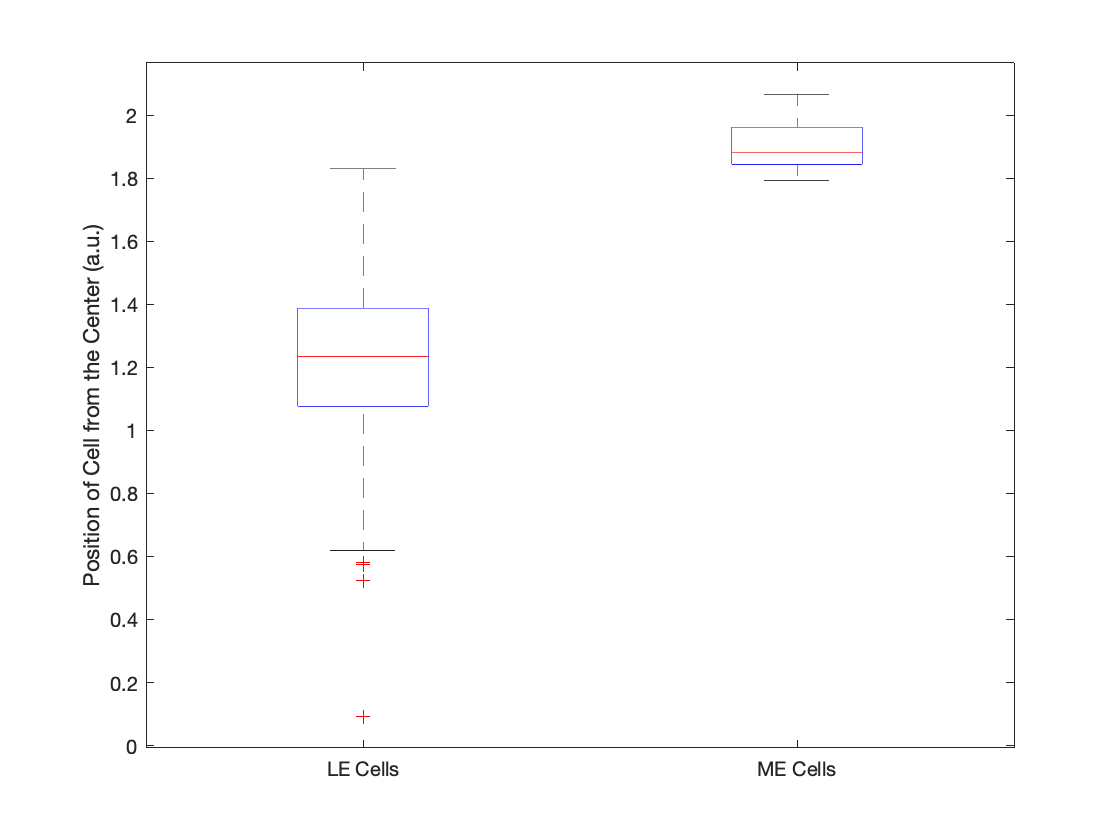

% Box plot final position of cells

figure 

MEB1KOluminal = MEB1KO_1_r(end,:);
MEB1KOmyo = MEB1KO_1_r2(end,:);
g = [MEB1KOluminal MEB1KOmyo];
C = [zeros(1,length(MEB1KOluminal)) ones(1,length(MEB1KOmyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_MEB1KO.pdf');

movefile('CellPosition_MEB1KO.pdf', folder);

% combine data from all experiments
MEB1KOLEposition = cat(1,MEB1KO_1_r(end,:),MEB1KO_2_r(end,:),MEB1KO_3_r(end,:),MEB1KO_4_r(end,:),MEB1KO_5_r(end,:));
MEB1KOMEposition = cat(1,MEB1KO_1_r2(end,:),MEB1KO_2_r2(end,:),MEB1KO_3_r2(end,:),MEB1KO_4_r2(end,:),MEB1KO_5_r2(end,:));

%Calculate Mean
MEB1KOLEaverage = mean(MEB1KOLEposition,2);
MEB1KOMEaverage = mean(MEB1KOMEposition,2);

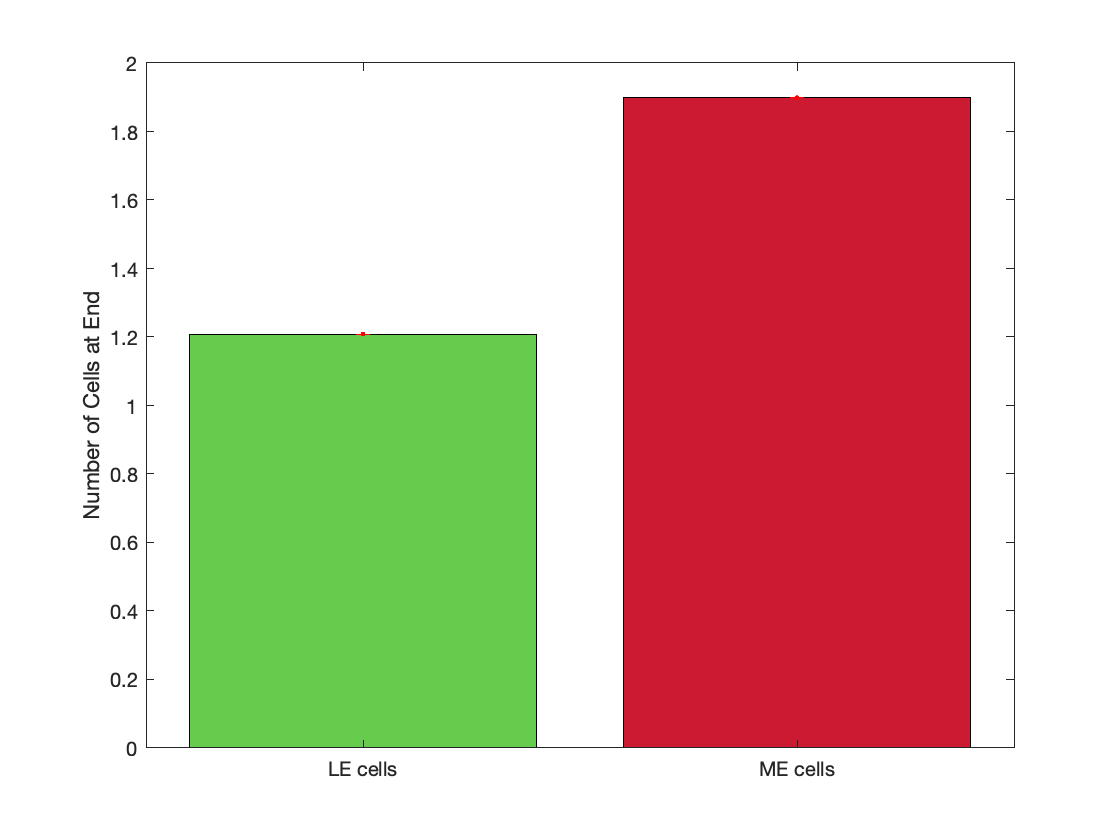

% plot average position of cells include data from all n=5 

%Calculate Mean and Standard Deviation
MEB1KOmeanLE = mean(MEB1KOLEaverage);
MEB1KOmeanME = mean(MEB1KOMEaverage);

y = cat(2, MEB1KOmeanLE, MEB1KOmeanME);

MEB1KOstdLE = std(MEB1KOLEaverage);
MEB1KOstdME = std(MEB1KOMEaverage);

error = cat(2, MEB1KOstdLE, MEB1KOstdME);

x=categorical({'LE cells', 'ME cells'});

b = bar(x,y);

%Make SD error bars 
hold on
errorbar(x,y, error, '.r')
hold off

ylabel('Number of Cells at End') 
ax.XTickLabels = {'LE Cells', 'ME Cells'};

b.FaceColor = 'flat';
b.CData(1,:) = [.4 .8 .3];
b.CData(2,:) = [.8 .1 .2];

hold off

folder = '~/Desktop/';
exportgraphics(gca, 'AverageCellPosition_MEB1KO.pdf');

movefile('AverageCellPosition_MEB1KO.pdf', folder);

## ME KO

### n=1

MEKO_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=1/results_from_time_0/location.dat";
[MEKO_1_LuminalPositions, MEKO_1_MyoepithelialPositions, MEKO_1_r, MEKO_1_r2] = CellPosition(MEKO_1);

### n=2

MEKO_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=2/results_from_time_0/location.dat";
[MEKO_2_LuminalPositions, MEKO_2_MyoepithelialPositions, MEKO_2_r, MEKO_2_r2] = CellPosition(MEKO_2);

### n=3

MEKO_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=3/results_from_time_0/location.dat";
[MEKO_3_LuminalPositions, MEKO_3_MyoepithelialPositions, MEKO_3_r, MEKO_3_r2] = CellPosition(MEKO_3);

### n=4

MEKO_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=4/results_from_time_0/location.dat";
[MEKO_4_LuminalPositions, MEKO_4_MyoepithelialPositions, MEKO_4_r, MEKO_4_r2] = CellPosition(MEKO_4);

### n=5

MEKO_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=5/results_from_time_0/location.dat";
[MEKO_5_LuminalPositions, MEKO_5_MyoepithelialPositions, MEKO_5_r, MEKO_5_r2] = CellPosition(MEKO_5);

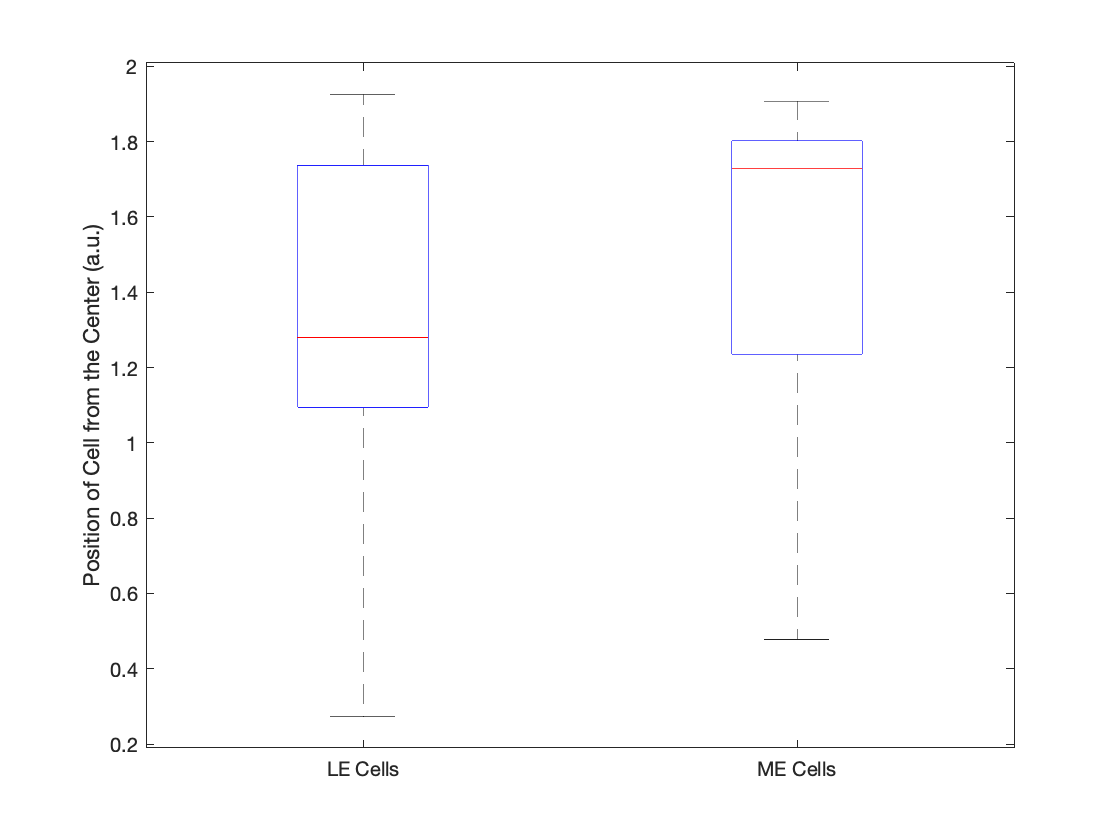

% Box plot final position of cells

figure 

MEKOluminal = MEKO_1_r(end,:);
MEKOmyo = MEKO_1_r2(end,:);
g = [MEKOluminal MEKOmyo];
C = [zeros(1,length(MEKOluminal)) ones(1,length(MEKOmyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_MEKO.pdf');

movefile('CellPosition_MEKO.pdf', folder);

% combine data from all experiments
MEKOLEposition = cat(1,MEKO_1_r(end,:),MEKO_2_r(end,:),MEKO_3_r(end,:),MEKO_4_r(end,:),MEKO_5_r(end,:));
MEKOMEposition = cat(1,MEKO_1_r2(end,:),MEKO_2_r2(end,:),MEKO_3_r2(end,:),MEKO_4_r2(end,:),MEKO_5_r2(end,:));

%Calculate Mean
MEKOLEaverage = mean(MEKOLEposition,2);
MEKOMEaverage = mean(MEKOMEposition,2);

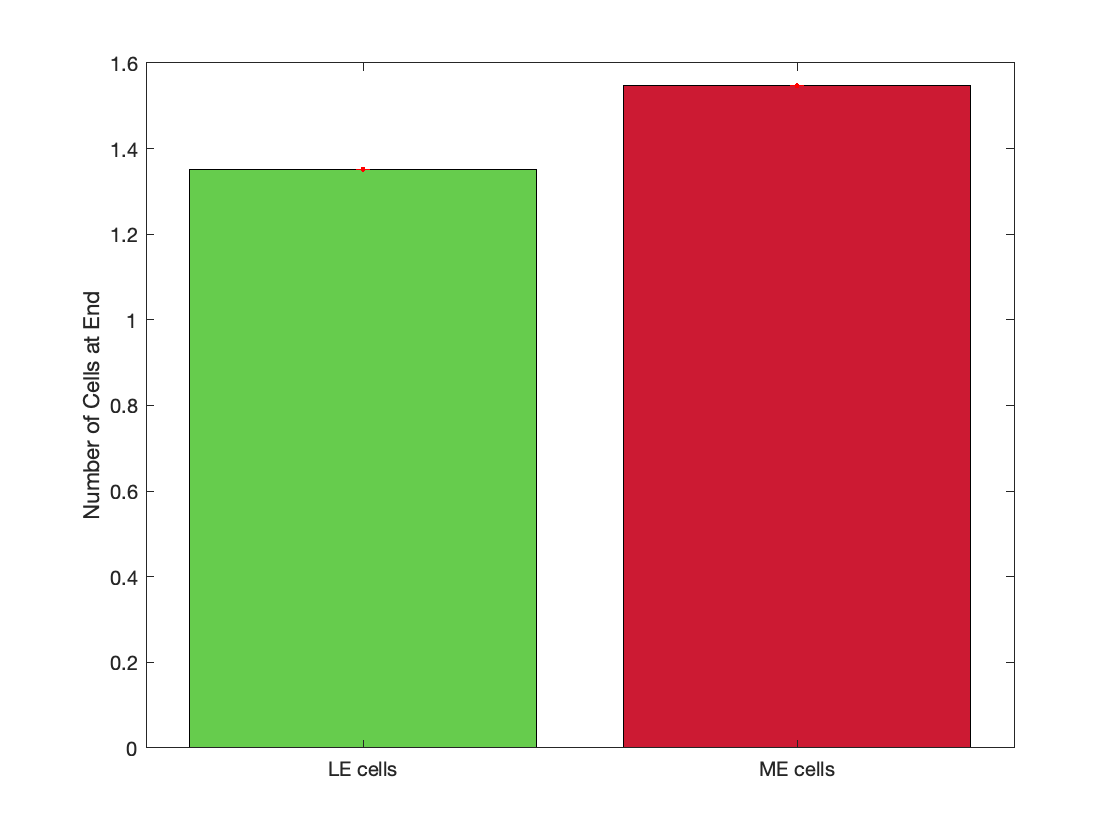

% plot average position of cells include data from all n=5 

%Calculate Mean and Standard Deviation
MEKOmeanLE = mean(MEKOLEaverage);
MEKOmeanME = mean(MEKOMEaverage);

y = cat(2,MEKOmeanLE, MEKOmeanME);

MEKOstdLE = std(MEKOLEaverage);
MEKOstdME = std(MEKOMEaverage);

error = cat(2,MEKOstdLE, MEKOstdME);

x=categorical({'LE cells', 'ME cells'});

b = bar(x,y);

%Make SD error bars 
hold on
errorbar(x,y, error, '.r')
hold off

ylabel('Number of Cells at End') 
ax.XTickLabels = {'LE Cells', 'ME Cells'};

b.FaceColor = 'flat';
b.CData(1,:) = [.4 .8 .3];
b.CData(2,:) = [.8 .1 .2];

hold off

folder = '~/Desktop/';
exportgraphics(gca, 'AverageCellPosition_MEKO.pdf');

movefile('AverageCellPosition_MEKO.pdf', folder);